# 基于PSO的系统参数识别仿真

 
clear;clc

## 1.系统参数设定

 
m = 5;
c = 20;
k = 100;

T = 20; % 仿真时间
dt = 0.001; % 仿真步长
time = 0 : dt : T; % 仿真时间向量

% PSO 参数
swarm_size = 80;  % 种群规模
max_iter = 270; % 最大迭代次数
v_mm = [-1 1]; %速度約束
c1 = 1.3; % 局部学习因子
c2 = 1.7; % 全局学习因子
w_mm = [0.1 0.9]; % 时变惯性权重約束
tolerance = 1e-21; % 容许误差

## 2.获取初始的响应序列

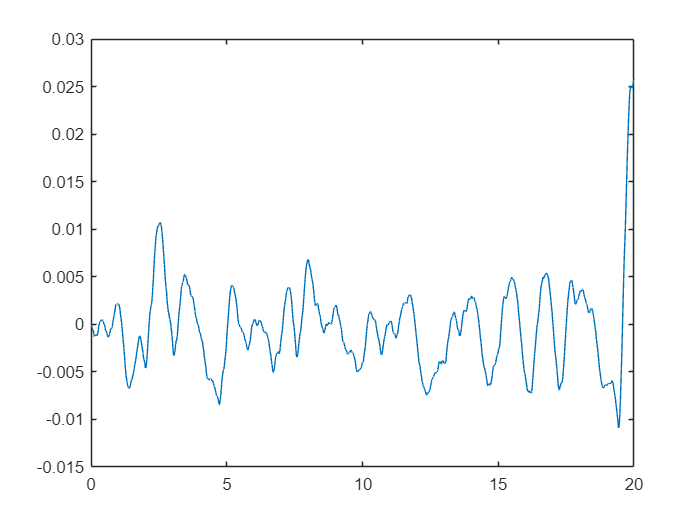

 
% 生成 MLS 信号
f = mls(length(time));
f = f(1:length(time),:);
% 将 MLS 信号的范围调整到 [-10, 10]
f = 10 .* (2 .* (f - min(f)) ./ (max(f) - min(f)) - 1);
u = f;
y_true = Function_LTI_ResponseLoss(m,c,k,u,1,dt,T);
figure
plot(time,y_true)

## 3.应用PSO工具箱求解

 
% 创建优化变量
m_hat = optimvar("m_hat","LowerBound",1,"UpperBound",10);
c_hat = optimvar("c_hat","LowerBound",0,"UpperBound",40);
k_hat = optimvar("k_hat","LowerBound",10,"UpperBound",200);

% 设置求解器的初始起点
initialPoint.m_hat = repmat(3,size(m_hat));
initialPoint.c_hat = repmat(10,size(c_hat));
initialPoint.k_hat = repmat(70,size(k_hat));

% 创建问题
problem = optimproblem;

% 定义问题目标
problem.Objective = fcn2optimexpr(@Function_LTI_ResponseLoss,m_hat,c_hat,k_hat,u,...
    y_true,dt,T);

% 设置非默认求解器选项
options = optimoptions("particleswarm","Display","iter","FunctionTolerance",...
    tolerance,"InertiaRange",w_mm,"MaxIterations",max_iter,"SelfAdjustmentWeight",c1,...
    "SocialAdjustmentWeight",c2,"SwarmSize",swarm_size,"PlotFcn","pswplotbestf");

% 显示问题信息
show(problem);


  OptimizationProblem : 

	Solve for:
       c_hat, k_hat, m_hat

	minimize :
       Function_LTI_ResponseLoss(m_hat, c_hat, k_hat, extraParams{1}, extraParams{2}, 0.001, 20)

       extraParams


	variable bounds:
       0 <= c_hat <= 40

       10 <= k_hat <= 200

       1 <= m_hat <= 10




% 求解问题
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","particleswarm","Options",options);

将使用 particleswarm 求解问题。

                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              80        0.002982          0.1694        0
    1             160        0.002982           10.94        0
    2             240        0.002982          0.6197        1
    3             320       0.0009345           0.287        0
    4             400       0.0009345          0.3607        1
    5             480       0.0009345           1.278        2
    6             560       0.0009345          0.3763        3
    7             640       0.0009345          0.3368        4
    8             720       0.0009345          0.3859        5
    9             800       0.0009345          0.3398        6
   10             880       0.0005012         0.03308        0
   11             960       0.0005012         0.02215        1
   12            1040        3.88e-05         0.01835        0
   13            1120   

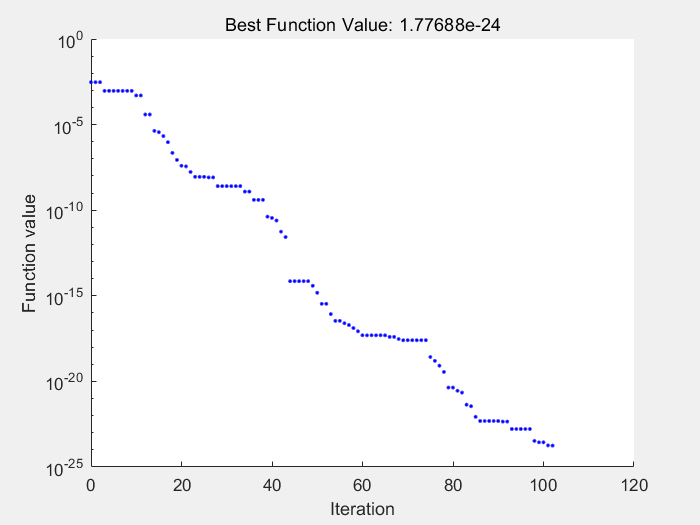

set(gca, 'YScale', 'log'); % 将当前图示的坐标转化为对数坐标


% 显示结果
solution

solution = 包含以下字段的 struct :
    c_hat: 20.0000
    k_hat: 100.0000
    m_hat: 5.0000


reasonSolverStopped

reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue

objectiveValue = 1.7769e-24


% 清除变量
clearvars m_hat c_hat k_hat initialPoint options reasonSolverStopped objectiveValue


## 4.非线性动力学系统辨识

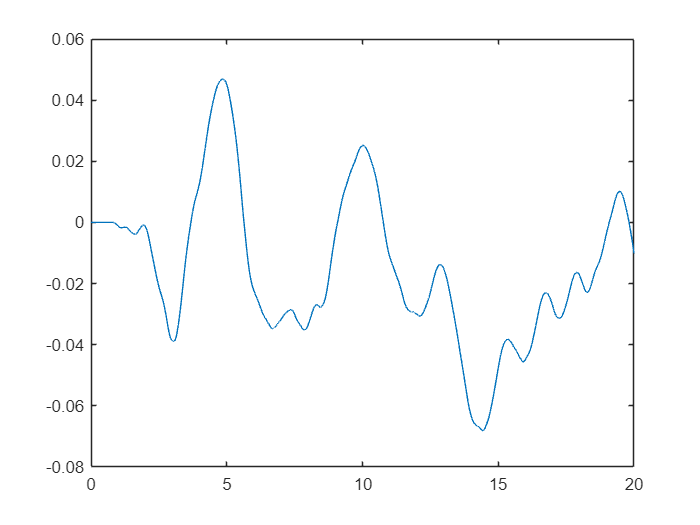

 
% 参数设定
Kp = 3;     % 比例增益
a = 1;      % s^3 项系数
b = 5;      % s^2 项系数
c = 9;      % s 项系数
d = 5;      % 常数项
Td = 0.8;   % 时滞时间
timen = 0 : 0.001 : 20; %系统运行时间

% 定义真实值传递函数的分子和分母
num_true = Kp;
den_true = [a, b, c, d];

% 获取真实的相应序列
% 生成 MLS 信号
fn = mls(length(timen));
fn = fn(1:length(timen),:);
% 将 MLS 信号的范围调整到 [-10, 10]
fn = 5 .* (2 .* (fn - min(fn)) ./ (max(fn) - min(fn)) - 1);
un = fn;
yn_true = Function_NTI_ResponseLoss(num_true,den_true,Td,un,1,timen);
figure
plot(time,yn_true)


% 利用PSO工具箱求解
% 分子分母上下界设定
num_min = 0; 
num_max = 10;
den_min = [0.1,0.1,0.1,0.1];
den_max = [10,10,10,10];

% 创建优化变量
num_hat = optimvar("num_hat","LowerBound",num_min,"UpperBound",num_max);
den_hat = optimvar("den_hat",1,4,"LowerBound",den_min,"UpperBound",den_max);
Td_hat = optimvar("Td_hat","LowerBound",0,"UpperBound",1);

% 设置求解器的初始起点
initialPoint2.num_hat = 1;
initialPoint2.den_hat = [1 1 1 1];
initialPoint2.Td_hat = repmat(0.2,size(Td_hat));

% 创建问题
problem2 = optimproblem;

% 定义问题目标
problem2.Objective = fcn2optimexpr(@Function_NTI_ResponseLoss,num_hat,den_hat,Td_hat,un,...
    yn_true,timen);

% 设置非默认求解器选项
options2 = optimoptions("particleswarm","Display","iter","FunctionTolerance",...
    tolerance,"InertiaRange",w_mm,"MaxIterations",max_iter,"SelfAdjustmentWeight",c1,...
    "SocialAdjustmentWeight",c2,"SwarmSize",swarm_size,"PlotFcn","pswplotbestf");

% 显示问题信息
show(problem2);


  OptimizationProblem : 

	Solve for:
       Td_hat, den_hat, num_hat

	minimize :
       Function_NTI_ResponseLoss(num_hat, den_hat, Td_hat, extraParams{1}, extraParams{2}, extraParams{3})

       extraParams


	


% 求解问题
[solution2,objectiveValue2,reasonSolverStopped2] = solve(problem2,initialPoint2,...
    "Solver","particleswarm","Options",options2);

将使用 particleswarm 求解问题。

                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              80           1.902       1.995e+06        0
    1             160           1.902       5.507e+08        0
    2             240          0.8749           107.5        0
    3             320          0.6108           36.54        0
    4             400          0.6108       1.189e+13        1
    5             480          0.6108       1.527e+20        2
    6             560          0.6108       2.953e+09        3
    7             640          0.1496       3.673e+17        0
    8             720          0.1496       3.474e+04        1
    9             800          0.1496            9855        2
   10             880          0.1496       7.815e+16        3
   11             960          0.1496       1.293e+10        4
   12            1040          0.1496           44.84        5
   13            1120   

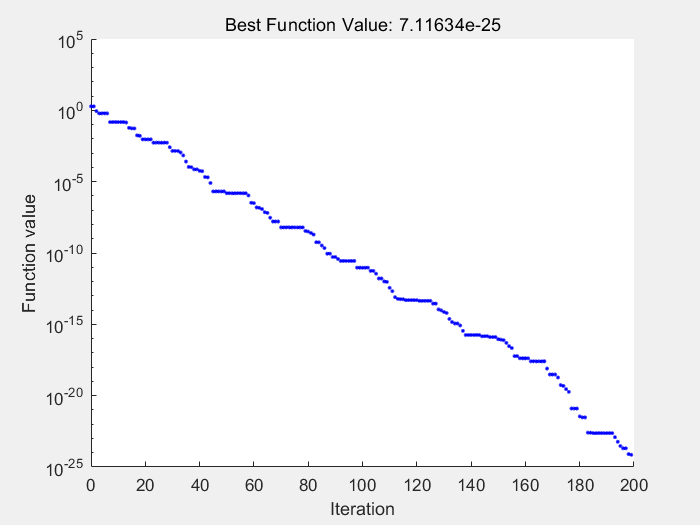

set(gca, 'YScale', 'log'); % 将当前图示的坐标转化为对数坐标


% 显示结果
solution2

solution2 = 包含以下字段的 struct :
     Td_hat: 0.8000
    den_hat: [0.8696 4.3479 7.8262 4.3479]
    num_hat: 2.6087


reasonSolverStopped2

reasonSolverStopped2 =     SolverConvergedSuccessfully


objectiveValue2

objectiveValue2 = 7.1163e-25

% 清除变量
clearvars num_hat den_hat Td_hat initialPoint2 options2 reasonSolverStopped objectiveValue